% generate a signal
function [signal] = generate_sinusoid(a, f, phi, t)
    signal =a*sin(2*pi*f*t + phi);
end 

% create parameters
a=1;
f=420;
fs=10000;
phi=0;
t=0:1/fs:0.5-(1/fs);

% create clean signal
signal_420Hz=generate_sinusoid(a, f, phi, t);

% play the sound
sound(signal_420Hz, fs);

% import singing signal
path_2_wav = ['C:\Users\frija\OneDrive\Documents\EPFL\BA5\signaux et systemes', filesep];    % the path to the data
fname = 'singing.wav';                                 % a file name stored in a string variable
[y_sing, fs_y_sing] = audioread([path_2_wav, fname]);

% know how long the signal is
info = audioinfo('singing.wav');
duree = info.Duration;
fprintf(' The audio file is %.2f seconds.\n', duree);

 The audio file is 1.00 seconds.


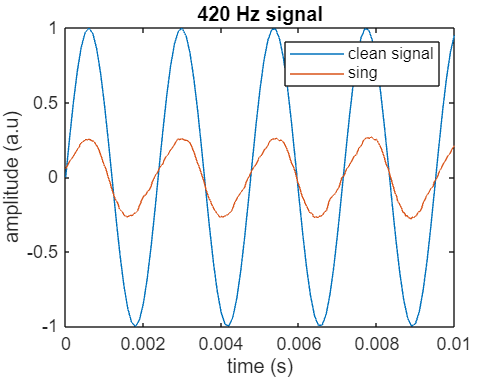

% Set the signal at the wanted length
wanted_duration = 0.5;

nb_samples = round(wanted_duration * fs_y_sing);

y_sing = y_sing(1:nb_samples);
t_sing=0:1/fs_y_sing:wanted_duration-(1/fs_y_sing); % Extract the wanted signal

% plot the two signals
figure;
plot(t, signal_420Hz,t_sing, y_sing);
title('420 Hz signal')
xlabel('time (s)');
ylabel('amplitude (a.u)')
legend({'clean signal','sing'})
xmin=0;
xmax=0.01;
xlim([xmin xmax]) 


% make the spectrum function 
function [Y, freq] = make_spectrum(signal, fs)
Y = fft(signal); % compute spectrum (note: it will be complex-valued).
Y = abs(Y/(length(signal))); % The FFT needs to be scaled in order to give a physically plausible scaling.

T0=(length(signal))/fs;
delta_f = 1/T0
frequneg= (-fs/2)+delta_f:delta_f:-delta_f;
freqpos= 0:delta_f:fs/2;
freq= [freqpos, frequneg];

Y = Y(:);
freq = freq(:);

end

% Compute the frequency spectra of the signals
[Y, freqs] = make_spectrum(signal_420Hz, fs);

delta_f = 2

[Y_sing, freqs_sing] = make_spectrum(y_sing, fs_y_sing);

delta_f = 2

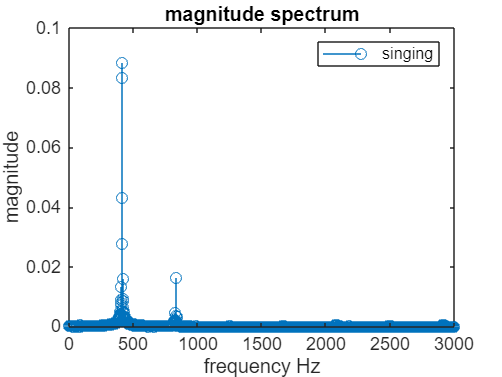


%make the magnitude spectra in dB
magnitude=abs(Y);
magnitude_dB= 20*log10(abs(Y));

magnitude_sing=abs(Y_sing);
magnitude_dB_sing= 20*log10(abs(magnitude_sing));

% plot the magnitude 
figure;
%stem(freqs, magnitude)
stem(freqs_sing, magnitude_sing)
title('magnitude spectrum');
xlabel('frequency Hz');
ylabel('magnitude');
legend({'singing'})
xmin=0;
xmax=3000;
xlim([xmin xmax]) 

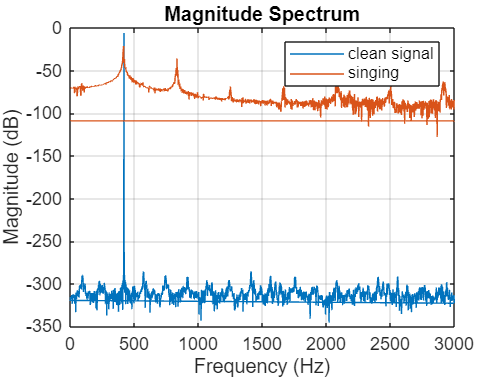


% Plot the magnitude spectrum in dB
figure;
plot(freqs, magnitude_dB, freqs_sing, magnitude_dB_sing);
title('Magnitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend({'clean signal','singing'})
grid on;
xmin=0;
xmax=3000;
xlim([xmin xmax])  